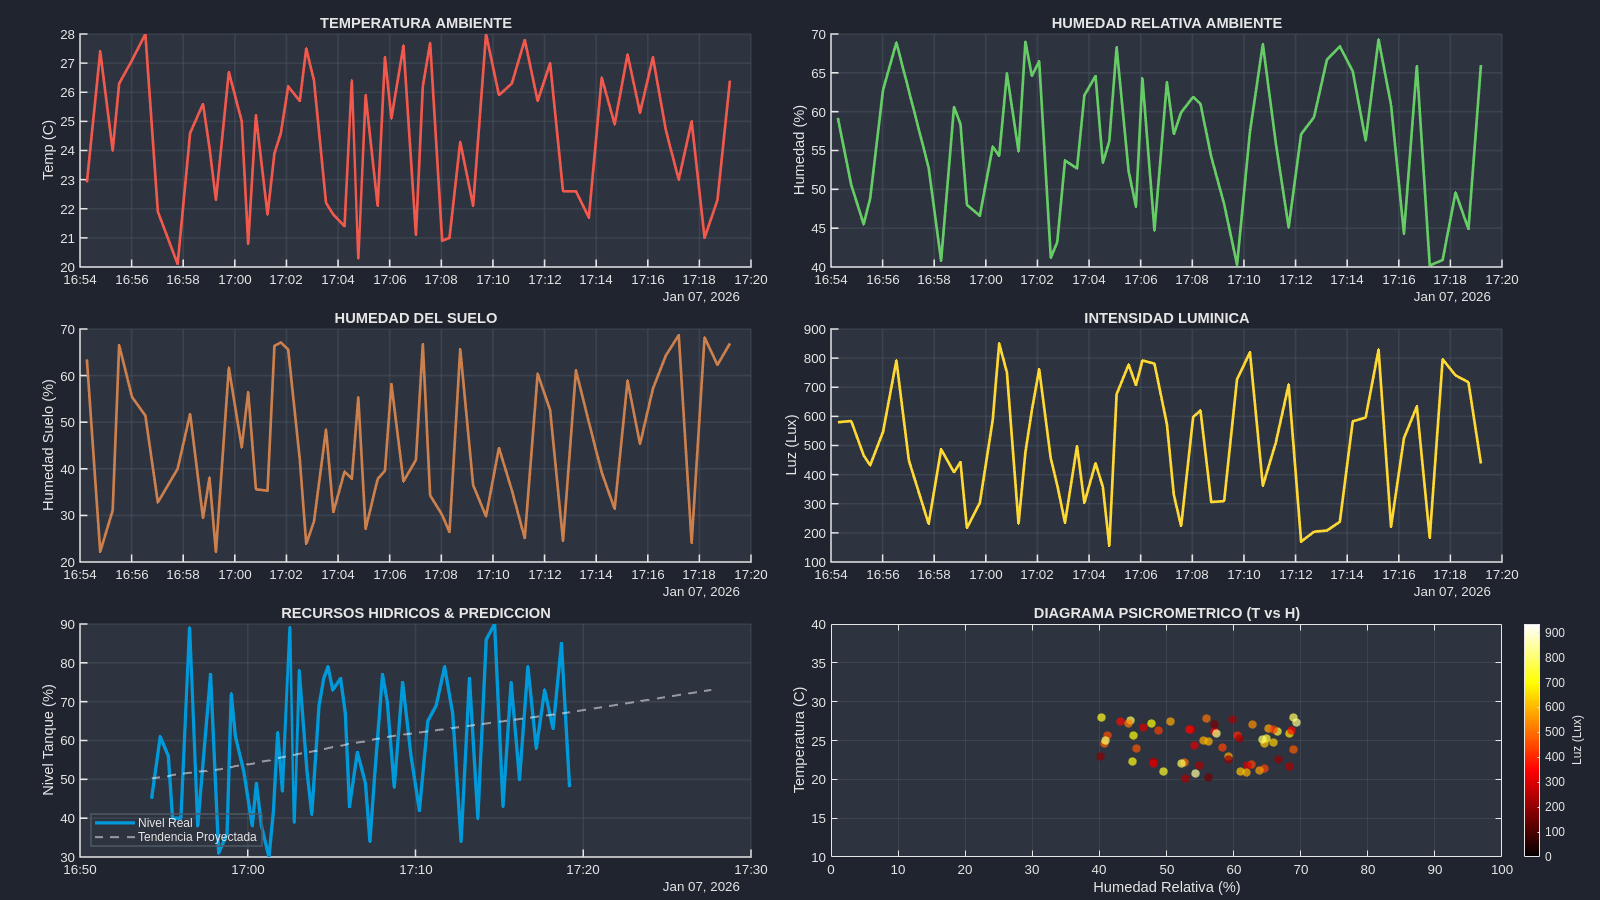

===== ESTADO SISTEMA [17:19:22] =====


Temperatura    : 26.4 C


Humedad Amb.   : 66.0 %


Humedad Suelo  : 66.9 %


Luz            : 438 Lux


Nivel Tanque   : 48.0 %


Prediccion     : SISTEMA ESTABLE


===== ESTADO SISTEMA [17:19:37] =====


Temperatura    : 26.4 C


Humedad Amb.   : 66.0 %


Humedad Suelo  : 66.9 %


Luz            : 438 Lux


Nivel Tanque   : 48.0 %


Prediccion     : SISTEMA ESTABLE


===== ESTADO SISTEMA [17:19:53] =====


Temperatura    : 28.0 C


Humedad Amb.   : 68.2 %


Humedad Suelo  : 47.3 %


Luz            : 404 Lux


Nivel Tanque   : 50.0 %


Prediccion     : SISTEMA ESTABLE


===== ESTADO SISTEMA [17:20:08] =====


Temperatura    : 28.0 C


Humedad Amb.   : 68.2

raw = fileread('./infra/matlab/secrets.json');
settings = jsondecode(raw);

channelID = settings.channelID;
readKey = settings.readAPIKey;

%% CONFIGURACIÓN ESTÉTICA PROFESIONAL
% Esquema de colores "Dark Engineering"
bg_color = [0.12 0.14 0.18];    % Fondo general (Gris azulado oscuro)
ax_color = [0.18 0.20 0.25];    % Fondo de ejes
grid_color = [0.30 0.35 0.40];  % Color de rejilla
text_color = [0.90 0.90 0.90];  % Texto principal
accent_temp = [0.95 0.35 0.30]; % Rojo temperatura
accent_hum = [0.40 0.80 0.40];  % Verde humedad
accent_luz = [1.00 0.85 0.20];  % Amarillo luz
accent_tanque = [0.00 0.60 0.85]; % Cyan tanque
accent_suelo = [0.80 0.50 0.30]; % Naranja tierra

%% INICIALIZACIÓN DE FIGURA EXPANDIDA (3x2 Grid)
fig = figure('Color', bg_color, 'Position', [50, 50, 1600, 900], ...
    'Name', 'GREENHOUSE MONITOR SYSTEM v2.0 - FULL ANALYTICS', 'NumberTitle', 'off');

% Layout principal: 3 filas x 2 columnas
tiledlayout(3, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

%% FILA 1: SENSORES INDIVIDUALES (Temperatura y Humedad Ambiente)

% --- Panel 1: TEMPERATURA ---
ax1 = nexttile;
h_temp = plot(ax1, NaT, NaN, 'Color', accent_temp, 'LineWidth', 2);
title(ax1, 'TEMPERATURA AMBIENTE', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
grid(ax1, 'on'); box(ax1, 'off');
ylabel(ax1, 'Temp (C)', 'Color', text_color);
set(ax1, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'LineWidth', 1.2);

% --- Panel 2: HUMEDAD AMBIENTE ---
ax2 = nexttile;
h_hum = plot(ax2, NaT, NaN, 'Color', accent_hum, 'LineWidth', 2);
title(ax2, 'HUMEDAD RELATIVA AMBIENTE', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
grid(ax2, 'on'); box(ax2, 'off');
ylabel(ax2, 'Humedad (%)', 'Color', text_color);
set(ax2, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'LineWidth', 1.2);

%% FILA 2: SENSORES INDIVIDUALES (Humedad Suelo y Luz)

% --- Panel 3: HUMEDAD DEL SUELO ---
ax3 = nexttile;
h_suelo = plot(ax3, NaT, NaN, 'Color', accent_suelo, 'LineWidth', 2);
title(ax3, 'HUMEDAD DEL SUELO', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
grid(ax3, 'on'); box(ax3, 'off');
ylabel(ax3, 'Humedad Suelo (%)', 'Color', text_color);
set(ax3, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'LineWidth', 1.2);

% --- Panel 4: LUZ AMBIENTE ---
ax4 = nexttile;
h_luz = plot(ax4, NaT, NaN, 'Color', accent_luz, 'LineWidth', 2);
title(ax4, 'INTENSIDAD LUMINICA', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
grid(ax4, 'on'); box(ax4, 'off');
ylabel(ax4, 'Luz (Lux)', 'Color', text_color);
set(ax4, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'LineWidth', 1.2);

%% FILA 3: ANÁLISIS AVANZADO (Tanque + Proyección | Correlación T-H)

% --- Panel 5: TANQUE + PREDICCIÓN ---
ax5 = nexttile;
hold(ax5, 'on');
h_tanque = plot(ax5, NaT, NaN, 'Color', accent_tanque, 'LineWidth', 2.5);
h_pred = plot(ax5, NaT, NaN, '--', 'Color', [1 1 1 0.5], 'LineWidth', 1.5);
title(ax5, 'Nivel del tanque de agua respecto al tiempo', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
grid(ax5, 'on'); box(ax5, 'off');
ylabel(ax5, 'Nivel Tanque (%)', 'Color', text_color);
legend(ax5, {'Nivel Real', 'Tendencia Proyectada'}, 'TextColor', text_color, ...
    'Color', 'none', 'EdgeColor', grid_color, 'Location', 'southwest');
set(ax5, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'LineWidth', 1.2);

% --- Panel 6: CORRELACIÓN T vs H (Scatter coloreado por Luz) ---
ax6 = nexttile;
h_scatter = scatter(ax6, [], [], 40, [], 'filled', 'MarkerFaceAlpha', 0.7);
title(ax6, 'DIAGRAMA PSICROMETRICO (T vs H)', 'Color', text_color, 'FontWeight', 'bold', 'FontSize', 11);
xlabel(ax6, 'Humedad Relativa (%)', 'Color', text_color);
ylabel(ax6, 'Temperatura (C)', 'Color', text_color);
grid(ax6, 'on'); box(ax6, 'on');
xlim(ax6, [0 100]); ylim(ax6, [10 40]);
colormap(ax6, 'hot'); % Mapa de color para visualizar intensidad de luz
c = colorbar(ax6, 'Color', text_color);
c.Label.String = 'Luz (Lux)';
c.Label.Color = text_color;
set(ax6, 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4);

%% BUCLE DE ACTUALIZACIÓN EN VIVO
while true
    try
        % A. LECTURA DE DATOS
        [data, time] = thingSpeakRead(channelID, 'ReadKey', readKey, 'NumPoints', 60);

        if ~isempty(data)
            % B. PROCESAMIENTO Y LIMPIEZA
            T = array2table(data, 'VariableNames', {'Temp', 'HumAmb', 'HumSuelo', 'Luz', 'Tanque'});
            T.Time = time;
            T_clean = rmmissing(T_clean);
            T_clean = fillmissing(T, 'previous');

            % C. CÁLCULO DE FRECUENCIA (Para predicción)
            if height(T_clean) > 1
                dt = minutes(mean(diff(T_clean.Time)));
            else
                dt = 0.25;
            end

            % D. ANÁLISIS PREDICTIVO (Tanque)
            x = (1:height(T_clean))';
            y = T_clean.Tanque;
            p = polyfit(x, y, 1); %Creo la pendiente y = mx + n.

            % Proyección visual futura
            x_pred = [x; (x(end)+1:x(end)+20)'];
            y_pred = polyval(p, x_pred);
            t_pred = [T_clean.Time; T_clean.Time(end) + minutes((1:20)'*dt)];

            if p(1) < -0.01
                muestras_fin = -p(2)/p(1) - height(T_clean);
                minutos_fin = muestras_fin * dt;
                msg_tanque = sprintf('VACIADO EN %.1f HORAS', minutos_fin/60);
            else
                msg_tanque = 'Nivel de agua estable';
            end

            % E. ACTUALIZACIÓN DE GRÁFICAS (Solo datos, no estructura)

            % Fila 1: Sensores básicos
            set(h_temp, 'XData', T_clean.Time, 'YData', T_clean.Temp);
            set(h_hum, 'XData', T_clean.Time, 'YData', T_clean.HumAmb);

            % Fila 2: Sensores secundarios
            set(h_suelo, 'XData', T_clean.Time, 'YData', T_clean.HumSuelo);
            set(h_luz, 'XData', T_clean.Time, 'YData', T_clean.Luz);

            % Fila 3: Análisis avanzados
            set(h_tanque, 'XData', T_clean.Time, 'YData', T_clean.Tanque);
            set(h_pred, 'XData', t_pred, 'YData', y_pred);

            set(h_scatter, 'XData', T_clean.HumAmb, 'YData', T_clean.Temp, 'CData', T_clean.Luz);
            caxis(ax6, [0 max(T_clean.Luz)*1.1]); % Escala dinámica

            % F. IMPRIMIR RESUMEN EN CONSOLA
            fprintf('===== ESTADO SISTEMA [%s] =====\n', datestr(now, 'HH:MM:SS'));
            fprintf('Temperatura    : %.1f C\n', T_clean.Temp(end));
            fprintf('Humedad Amb.   : %.1f %%\n', T_clean.HumAmb(end));
            fprintf('Humedad Suelo  : %.1f %%\n', T_clean.HumSuelo(end));
            fprintf('Luz            : %.0f Lux\n', T_clean.Luz(end));
            fprintf('Nivel Tanque   : %.1f %%\n', T_clean.Tanque(end));
            fprintf('Prediccion     : %s\n', msg_tanque);
            fprintf('========================================\n\n');

            drawnow limitrate;
        end

    catch ME
        fprintf('Error en ciclo: %s. Reintentando...\n', ME.message);
    end

    pause(15);
end